## P4 典型案例

## 4.1 倒立摆

虑一个二维问题，其中摆被约束在如下图所示的垂直平面内运动。对于该系统，控制输入是使小车沿水平方向运动的力 $F$，输出则是摆的角位置 $\theta$ 和小车的水平位置 $x$。

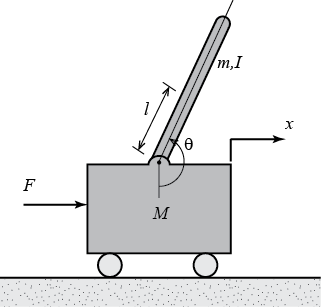

考虑以下物理量：

设计准则要求：摆在受到1 N·s大小的脉冲扰动后，必须在5秒内恢复到垂直向上位置，且偏离垂直方向的偏角不得超过0.05弧度。摆初始状态为垂直向上的平衡位置，$$\theta$ = $\pi$$。

综上所述，该系统的设计要求如下：

- $\theta$ 的稳定时间小于 5 秒

- 摆角 $\theta$ 与垂直方向的偏差绝不超过 0.05 弧度

### 4.1.1 受力分析与系统方程

以下是倒立摆系统中两个组成部分的自由体图。

## 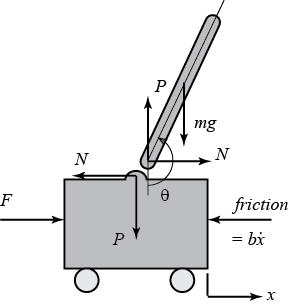

（小车）水平方向受力分析：


$$M\ddot x+ b\dot x + N= F$$


（摆）水平方向受力分析可得反作用力 $N$ 为


$$N=m\ddot x + ml\ddot \theta \cos \theta -ml \dot \theta^2 \sin \theta$$


（系统的第一个控制方程）结合以上等式，


$$(M+m)\ddot x + b\dot x + ml \ddot \theta \cos \theta -ml \dot \theta ^2 \sin \theta =F \quad \text{(1)}$$


（摆）水平方向受力分析，可得


$$P \sin \theta + N \cos \theta-mg\sin \theta=ml\ddot\theta+m\ddot x \cos \theta$$


（摆）以摆的质心为轴的力矩进行求和


$$-Pl\sin\theta-Nl\cos\theta=I\ddot{\theta}$$


（系统的第二个控制方程）结合以上等式，


$$(I+ml^2)\ddot{\theta}+mgl\sin\theta=-ml\ddot{x}\cos\theta \quad (2)$$


为了应用前文介绍的线性时不变系统分析工具，对方程（1）-（2）线性化处理。

具体而言，以垂直向上的平衡位置 $\theta \;\textrm{=}\;\pi$ 为基准对方程进行线性化，并假设系统始终位于该平衡点的小邻域内。设 $\phi$ 表示摆的位置相对于平衡位置的偏差，即 $\theta \;\textrm{=}\;\pi \;\textrm{+}\;\phi$。同样假设相对于平衡位置的偏差（$\phi$）很小，我们可以对系统方程中的非线性函数采用以下小角度近似：


$$\cos \theta =\cos (\pi +\phi )\approx -1$$



$$\sin \theta =\sin (\pi +\phi )\approx -\phi$$



$${\dot{\theta} }^2 ={\dot{\phi} }^2 \approx 0$$


将上述近似式代入非线性控制方程后，可得到两个线性化运动方程。注意，输入量 $F$ 已被 $u$ 替代。


$$(I+ml^2 )\ddot{\phi} -mgl\phi =ml\ddot{x}$$



$$(M+m)\ddot{x} +b\dot{x} -ml\ddot{\phi} =u$$


整理为一阶线性方程的标准形式：


$$$$
\left[{\begin{array}{c}
  \dot{x}\\ \ddot{x}\\ \dot{\phi}\\ \ddot{\phi}
\end{array}}\right] =
\left[{\begin{array}{cccc}
  0&1&0&0\\
  0&\frac{-(I+ml^2)b}{I(M+m)+Mml^2}&\frac{m^2gl^2}{I(M+m)+Mml^2}&0\\
  0&0&0&1\\
  0&\frac{-mlb}{I(M+m)+Mml^2}&\frac{mgl(M+m)}{I(M+m)+Mml^2}&0
\end{array}}\right]
\left[{\begin{array}{c}
  x\\ \dot{x}\\ \phi\\ \dot{\phi}
\end{array}}\right]+
\left[{\begin{array}{c}0\\
  \frac{I+ml^2}{I(M+m)+Mml^2}\\
  0 \\
  \frac{ml}{I(M+m)+Mml^2}
\end{array}}\right]u$$$$



$$$${ y} =
\left[{\begin{array}{cccc}
  0&0&1&0
\end{array}}\right]
\left[{\begin{array}{c}
  x\\ \dot{x}\\ \phi\\ \dot{\phi}
\end{array}}\right]+
\left[{\begin{array}{c}
  0\\0
\end{array}}\right]u$$$$


M = 0.5;
m = 0.2;
b = 0.1;
I = 0.006;
g = 9.8;
l = 0.3;

p = I*(M+m)+M*m*l^2; %denominator for the A and B matrices

A = [0      1              0           0;
     0 -(I+m*l^2)*b/p  (m^2*g*l^2)/p   0;
     0      0              0           1;
     0 -(m*l*b)/p       m*g*l*(M+m)/p  0];
B = [     0;
     (I+m*l^2)/p;
          0;
        m*l/p];
C = [0 0 1 0];
D = 0;

states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'u'};
outputs = {'phi'};

ip_sys = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)


ip_sys =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot          0  -0.1818    2.673        0
   phi            0        0        0        1
   phi_dot        0  -0.4545    31.18        0
 
  B = 
                u
   x            0
   x_dot    1.818
   phi          0
   phi_dot  4.545
 
  C = 
              x    x_dot      phi  phi_dot
   phi        0        0        1        0
 
  D = 
        u
   phi  0
 
连续时间状态空间模型。


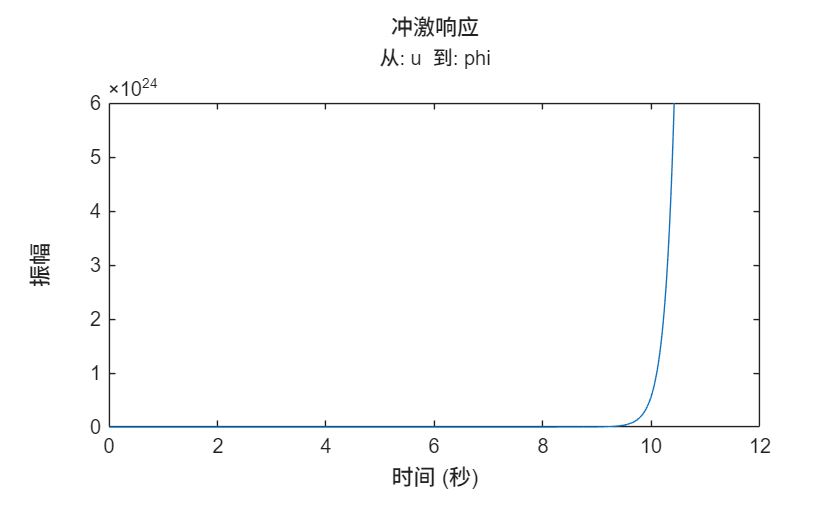

impulse(ip_sys)

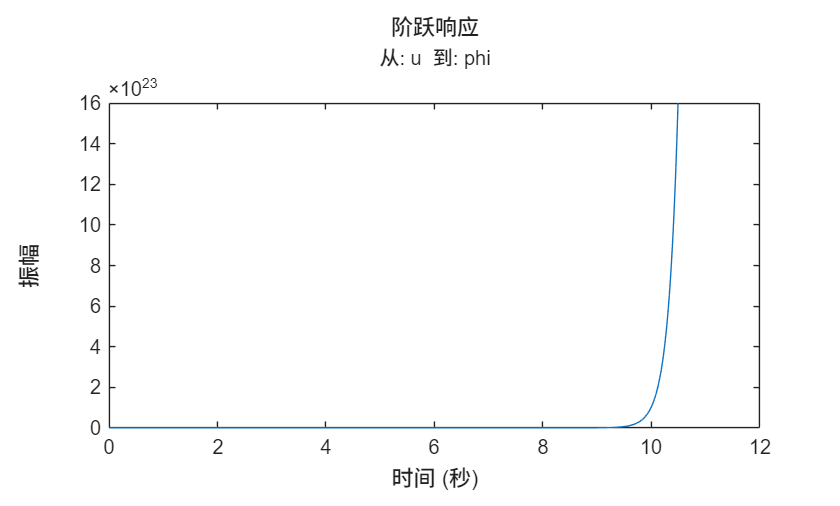

step(ip_sys)

由冲激响应和阶跃响应可得，系统在 $\theta = \pi$ 位置不稳定。

注意，**振幅发生有限时间逃逸，是因为做了线性化，换言之，当 **$\phi$** 偏离原点位置足够大时，线性模型已无法作为原系统的近似。**

### 4.1.2 PID控制

我们考虑摆的位置调整，设计准则如下：

- 调节时间小于5秒

- 摆偏离垂直方向的偏角不应超过0.05弧度

由于我们试图控制摆的位置（该位置应在初始扰动后恢复到垂直状态），因此我们追踪的参考信号应为零。此类情况通常被称为“调节器”问题。作用于小车上的外力可视为脉冲扰动。本题的原理图如下所示

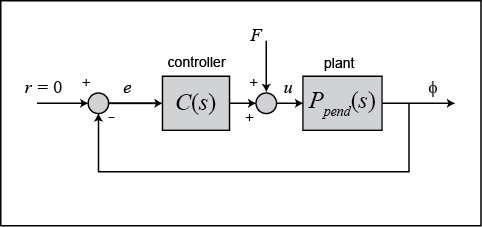

先将原理图按如下方式重新排列

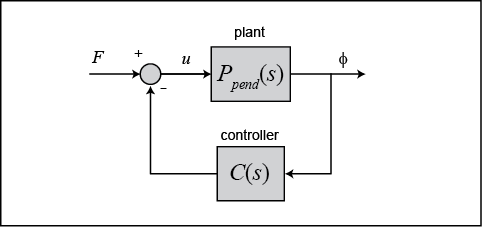

#### PID 参数选取

按以下步骤操作以获得理想的响应。

- 获取开环响应，并确定需要改进的地方

- 添加比例控制以改善上升时间

- 添加微分控制以减少超调

- 添加积分控制以减小稳态误差

- 调整各增益 $K_p$、$K_i$ 和 $K_d$，直至获得理想的整体响应。

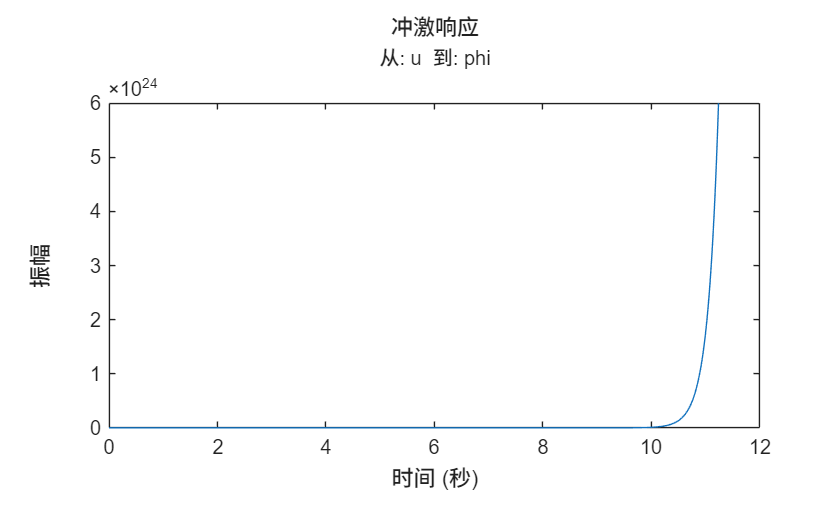

Kp = 1;
Ki = 0;
Kd = 0;
C = pid(Kp,Ki,Kd);
clp = feedback(ip_sys,C);

impulse(clp)

该响应仍然不稳定。让我们通过增大比例增益来修改响应。将 $K_p$ 变量增大，观察其对响应的影响。

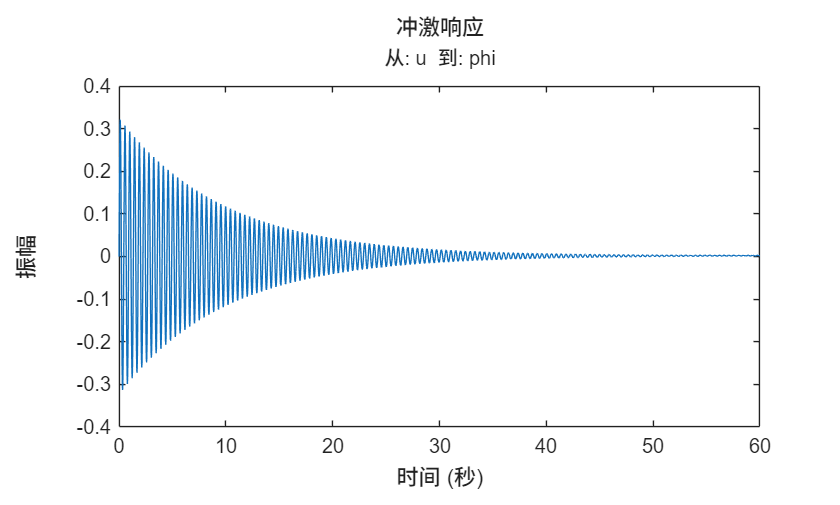

Kp = 50;
Ki = 0;
Kd = 0;
C = pid(Kp,Ki,Kd);
clp = feedback(ip_sys,C);

impulse(clp)

系统趋于稳定了，但是显然控制初期误差变化很快，增加微分项（预测项），抑制震荡

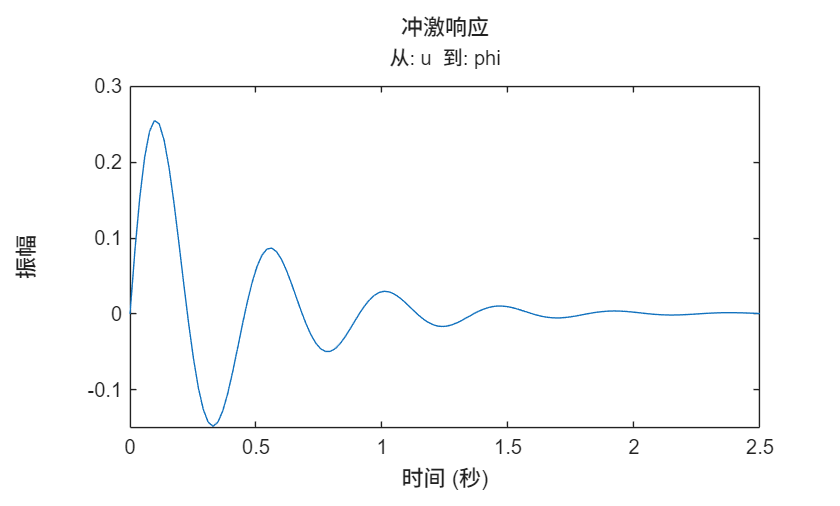

Kp = 50;
Ki = 0;
Kd = 1;
C = pid(Kp,Ki,Kd);
clp = feedback(ip_sys,C);

impulse(clp)

响应峰值不大于 0.05 弧度的要求。以通过增加微分控制量来减小超调量

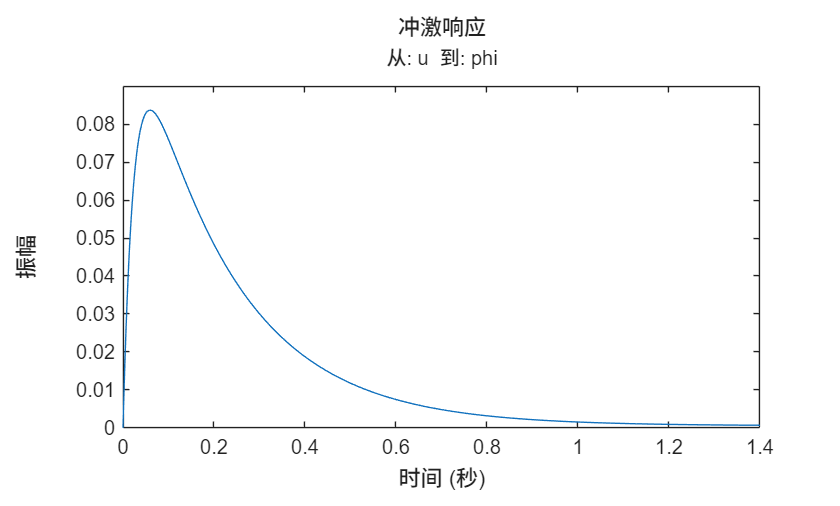

Kp = 50;
Ki = 0;
Kd = 10;
C = pid(Kp,Ki,Kd);
clp = feedback(ip_sys,C);

impulse(clp)

继续增加微分控制量来减小超调量

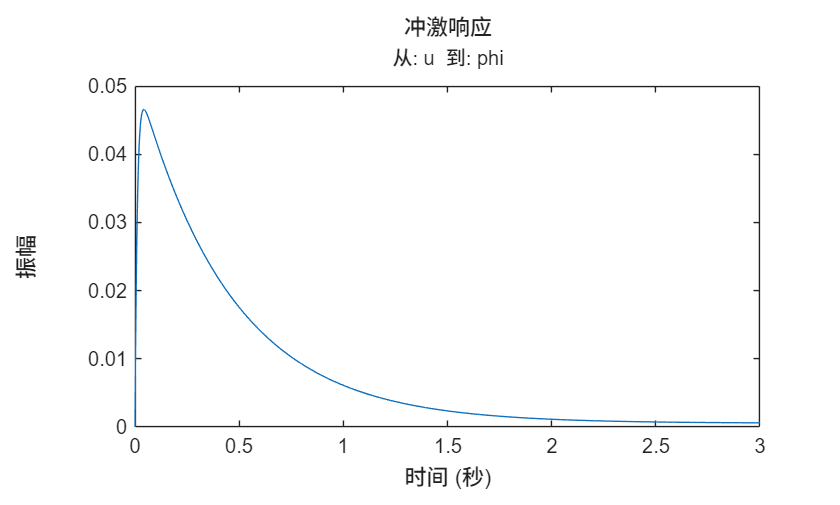

Kp = 50;
Ki = 0;
Kd = 20;
C = pid(Kp,Ki,Kd);
clp = feedback(ip_sys,C);

impulse(clp)

## 4.2 飞机俯仰

### 4.2.1 系统方程

设计一个用于控制飞机俯仰角的自动驾驶仪。

飞机的基本坐标轴以及作用在飞机上的力如下图所示。

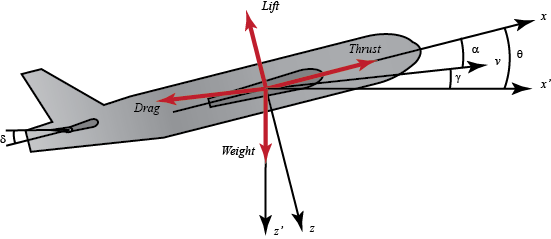

假设飞机在恒定高度和恒定速度下进行稳定巡航。因此，在 (x) 方向和 (y) 方向上，推力、阻力、重力和升力彼此平衡。我们还假设俯仰角发生变化时，飞机速度在任何情况下都不会改变（这个假设并不完全符合实际，但可以使问题得到一定程度的简化）。在这些假设下，飞机的纵向运动方程可写为：


$$\dot\alpha=\mu\Omega\sigma[-(C_L+C_D)\alpha+\frac{1}{(\mu-C_L)}q-(C_W \sin \gamma)\theta+C_L]$$



$$$$ \dot{\alpha} = \mu\Omega\sigma [-(C_L+C_D)\alpha+\frac{1}{(\mu-C_L)}q-(C_W \sin\gamma)\theta+C_L] $$
$$



$$\dot{\theta} =\Omega q$$


代入一些数值，以简化上文给出的建模方程：


$$\dot\alpha=-0.313\alpha+56.7q+0.232\delta$$



$$\dot q=-0.0139\alpha-0.426q+0.0203\delta$$



$$\dot \theta=56.7q$$


写成状态方程的形式


$$\left\lbrack \begin{array}{c}
\dot{\;\alpha } \\
\dot{q} \\
\dot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-0\ldotp 313 & 56\ldotp 7 & 0\\
-0\ldotp 0139 & -0\ldotp 426 & 0\\
0 & 56\ldotp 7 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha \\
q\\
\theta 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\ldotp 232\\
0\ldotp 0203\\
0
\end{array}\right\rbrack \left\lbrack \delta \right\rbrack$$


由于我们的输出是俯仰角，因此输出方程如下。


$$y=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha \\
q\\
\theta 
\end{array}\right\rbrack$$


A = [-0.313 56.7 0; -0.0139 -0.426 0; 0 56.7 0];
B = [0.232; 0.0203; 0];
C = [0 0 1];
D = 0;
pitch_ss = ss(A,B,C,D)


pitch_ss =
 
  A = 
            x1       x2       x3
   x1   -0.313     56.7        0
   x2  -0.0139   -0.426        0
   x3        0     56.7        0
 
  B = 
           u1
   x1   0.232
   x2  0.0203
   x3       0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。


### 4.2.2 观察系统的开环响应

#### a. 阶跃响应

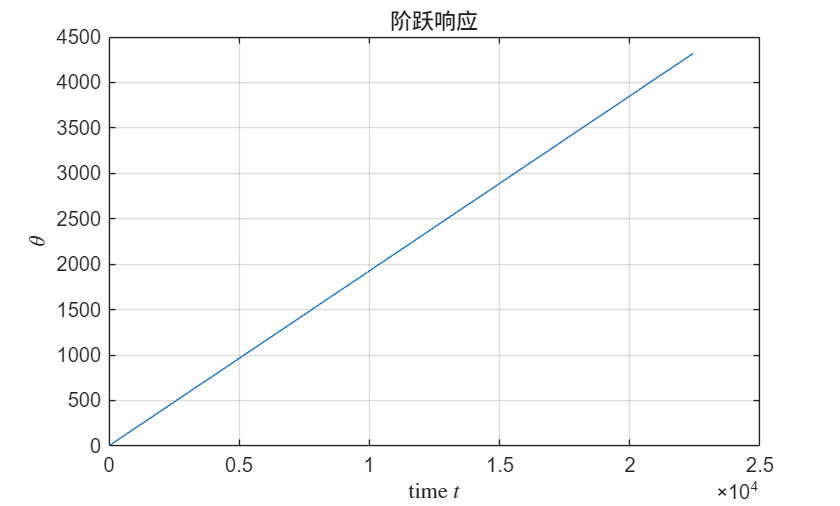

[z,tOut] = step(pitch_ss);

figure()
plot(tOut,z)
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('${\theta}$','Interpreter','latex')
title('阶跃响应')

显然，系统不稳定

#### b. 冲激响应

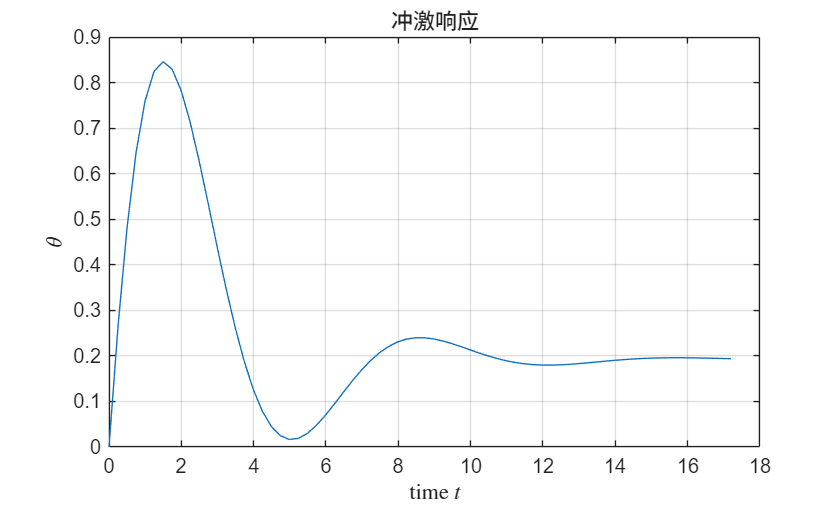

[z,tOut] = impulse(pitch_ss);

figure()
plot(tOut,z)
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('${\theta}$','Interpreter','latex')
title('冲激响应')

### 4.2.3 PID 控制

要求：对于 0.2 弧度的阶跃参考信号，设计准则如下：

- 超调量小于 10%

- 上升时间小于 2 秒

- 稳定时间小于 10 秒

- 稳态误差小于 2%

采用如下的控制结构

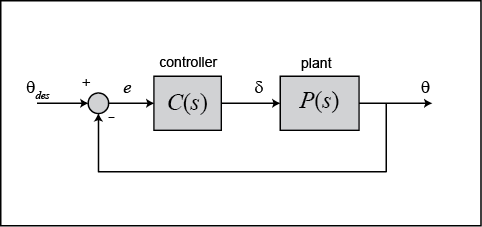

pidTuner(0.2*pitch_ss, 'pid')

一组合适的参数为

Kp = 41.5;
Ki = 16.3;
Kd = 20.8;
c_pid = pid(Kp,Ki,Kd)


c_pid =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  且 Kp = 41.5, Ki = 16.3, Kd = 20.8
 
并联型的连续时间 PID 控制器。


clp_2 = feedback(c_pid*0.2*pitch_ss,1)


clp_2 =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1         0         0         0         0         0         1
   x2         0         1         0         0         0         0
   x3         0         0         1         0         0        -1
   x4   -0.7563   -0.9651         0    -0.313      56.7    -1.926
   x5  -0.06618  -0.08445         0   -0.0139    -0.426   -0.1685
   x6         0         0         0         0      56.7         0
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4   0.232
   x5  0.0203
   x6       0
 
  C = 
         x1    x2    x3    x4    x5    x6
   y1  3.26  4.16     0     0     0   8.3
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3  x4  x5  x6
   x1   1   0   0   0   0   0
   x2   0   0   1   0   0   0
   x3   0   0   0   0   0   0
   x4   0   0   0   1   0   0
   x5   0   0   0   0   1   0
   x6   0   0   0   0   0   1
 
连续时间状态空间模型。


采用线性系统仿真器验证

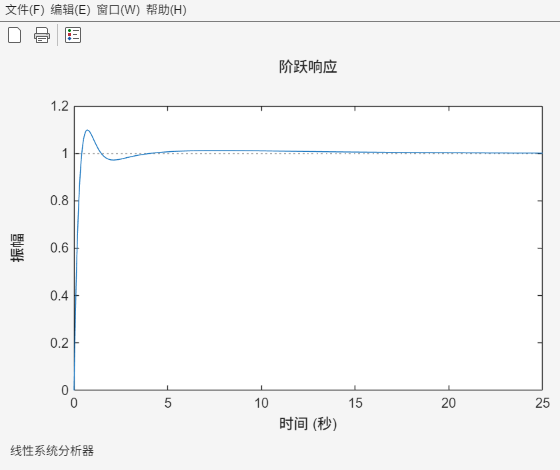

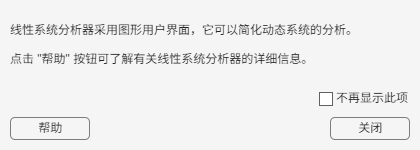

linearSystemAnalyzer(clp_2)